# Analysis of Robust Stability (RS) and Robust Performance (RP)

load statespace_data A B C D FWT

% 2 inputs, 2 outputs
s = tf('s');
G = FWT(1:2, 1:2);

% performance weights
wp = [(s/3+0.3*2*pi)/(s+pi*6e-5) 0;
    0 0.05];

wu = [0.005 0;
       0 (0.005*s^2 + 0.0007*s+0.00005)/(s^2 + 0.0014*s + 10^(-6))];

% uncertainty weights
wi1 = ((1/(16*pi))*s + 0.3)/((1/(64*pi))*s + 1);
wi2 = wi1;

wo1 = (0.05*s + 0.25)/(0.01*s + 1);
wo2 = wo1;

wi = [wi1 0;
      0 wi2];
wo = [wo1 0;
     0 wo2];

## 3. Frequency response of weights

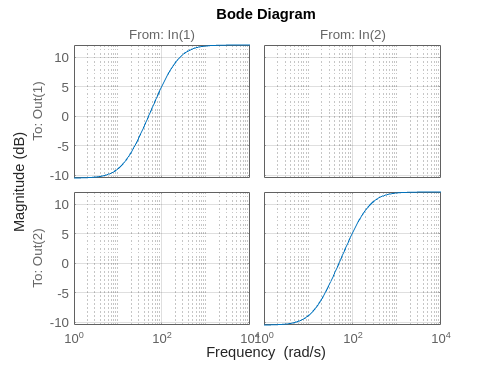

% frequency response of uncertainty weights
figure
bodemag(wi)
grid on

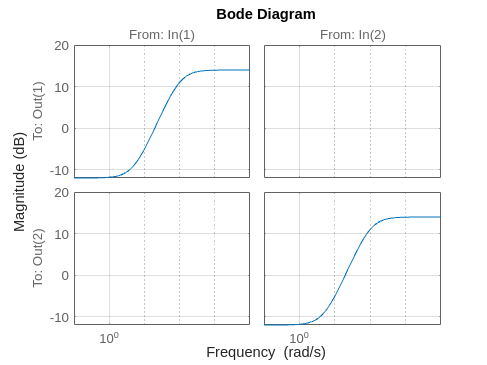


figure
bodemag(wo)
grid on


% uncertain TF singular values 

pb1 = [ultidyn("idelta1", 1) 0; 0 ultidyn("idelta2", 1)];
pb2 = [ultidyn("odelta1", 1) 0; 0 ultidyn("odelta2", 1)];

wid = wi*pb1;
wod = wo*pb2;

X = (eye(2)+wod)*G*(eye(2)+wid);
X.u = 'u'

Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 9 states.
The model uncertainty consists of the following blocks:
  idelta1: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  idelta2: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  odelta1: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  odelta2: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences


X.y = 'ydy'

Uncertain continuous-time state-space model with 2 outputs, 2 inputs, 9 states.
The model uncertainty consists of the following blocks:
  idelta1: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  idelta2: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  odelta1: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences
  odelta2: Uncertain 1x1 LTI, peak gain = 1, 1 occurrences


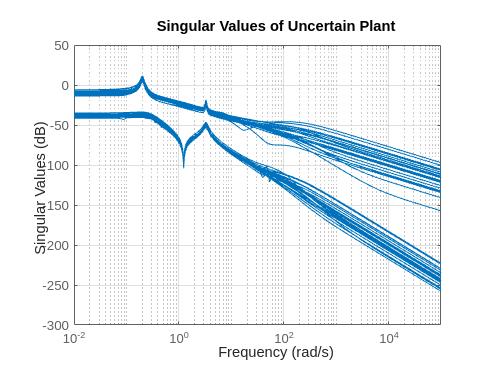


figure
sigma(X)
title('Singular Values of Uncertain Plant')
grid on

## 4. Augmented Generalised Plant

% Define plant and in- and outputs
G.u = 'udu';
G.y = 'y';

wp.u = 'v';
wp.y = 'z1';

wu.u = 'u';
wu.y = 'z2';

wo.u = 'y';
wo.y = 'do';

wi.u = 'u';
wi.y = 'di';

% Build system
sumblock1 = sumblk("ydy = y + dy", 2);
sumblock2 = sumblk("udu = u + du", 2);
sumblock3 = sumblk("v = w + ydy", 2);

dP = connect(G, wp, wu, wi, wo, sumblock1, sumblock2, sumblock3, {'du', 'dy', 'w', 'u'}, {'di', 'do', 'z1', 'z2', 'v'});

## 5. Checking NS, NP, RS, RP

load mixedsensitivitycontroller.mat MS_C P CLms Kfb_opt CLsysd CL_mimocontroller

K = MS_C;
Kfb_opt.u = 'v';

Kfb_opt =
 
  From input "v(1)" to output...
          41.39 s + 3.642
   u(1):  ---------------
                 s
 
            s^2 + 89.61 s + 1.118
   u(2):  -------------------------
          s^2 - 0.05891 s + 0.04157
 
  From input "v(2)" to output...
   u(1):  0
 
   u(2):  0
 
Continuous-time transfer function.
Model Properties


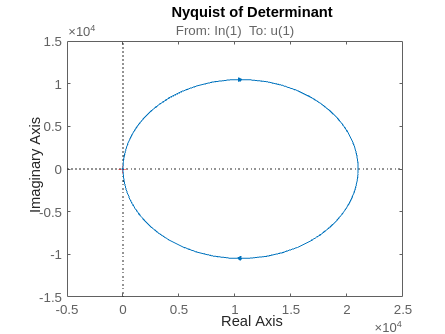


% NS - generalised Nyquist
ol = K*G;
tdet = eye(2) - ol;

det = tdet(1,1)*tdet(2,2) - tdet(1,2)*tdet(2,1);

nyquist(det);
title('Nyquist of Determinant')


% NP - ||N||inf < 1
gamma = hinfnorm(CLms);

% RS
N = lft(dP, K);
M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,1000);
Mf=frd(M,omega);
blockstructure =  ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 1000/1000



% norm of bound
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.7471


% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 1000/1000



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 1.3648

# 2.2 Robust Controller Design

## 2.1 DK design

%D-K iterations

Delta=[ultidyn('D_1',[1,1]) 0 0 0; 0 ultidyn('D_2',[1,1]) 0 0; 0 0 ultidyn('D_3',[1,1]) 0; 0 0 0 ultidyn('D_4',[1,1])];

Punc=lft(Delta,dP);
opt = musynOptions('RandomStart', 3)

opt =   musyn with properties:

          Display: 'short'
          MaxIter: 10
       TargetPerf: 0
          TolPerf: 0.0100
          MixedMU: 'off'
           FullDG: [1 1]
         FitOrder: [5 2]
    FrequencyGrid: [0×1 double]
        AutoScale: 'on'
       Regularize: 'on'
        LimitGain: 'on'
      RandomStart: 3
      UseParallel: 0
         MinDecay: 1.0000e-07
     MaxFrequency: Inf



[DK, clp, dkinfo]=musyn(Punc,2,2);



D-K ITERATION SUMMARY:
-----------------------------------------------------------------
                       Robust performance               Fit order
-----------------------------------------------------------------
  Iter         K Step       Peak MU       D Fit             D
    1           12.74        9.289        9.382            22
    2           6.554        6.487        6.503            20
    3           2.345        2.055         2.07            34
    4           1.232        1.221        1.246            36
    5           1.024        1.019        1.106            30
    6          0.9769       0.9728        1.028            36
    7          0.9688       0.9662        1.029            32
    8          0.9762       0.9734       0.9979            38

Best achieved robust performance: 0.966



DK.u = 'v'

DK =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48
   x1   -0.0001313      0.3141     -0.1885      0.4258      0.5447   0.0001015    -0.01459    -0.03354     0.02249     0.05483      0.1199        1.67      -5.128      0.1129    -0.05303     -0.2601     -0.4409    0.007929        6.67      -8.438      0.2155     -0.1305      0.3613       9.954     0.01753      0.8793    -0.07201   -0.004968      -16.44     0.02146    0.005256      0.1711      -0.124 

DK.y = 'u'

DK =
 
  A = 
                x1          x2          x3          x4          x5          x6          x7          x8          x9         x10         x11         x12         x13         x14         x15         x16         x17         x18         x19         x20         x21         x22         x23         x24         x25         x26         x27         x28         x29         x30         x31         x32         x33         x34         x35         x36         x37         x38         x39         x40         x41         x42         x43         x44         x45         x46         x47         x48
   x1   -0.0001313      0.3141     -0.1885      0.4258      0.5447   0.0001015    -0.01459    -0.03354     0.02249     0.05483      0.1199        1.67      -5.128      0.1129    -0.05303     -0.2601     -0.4409    0.007929        6.67      -8.438      0.2155     -0.1305      0.3613       9.954     0.01753      0.8793    -0.07201   -0.004968      -16.44     0.02146    0.005256      0.1711      -0.124 

## 2.2 Checking Performances of DK

% NS and NP
NS = max(real(eig(N)))

NS = -1.8850e-04


% RS and RP
N = lft(dP, DK);

N22 = N(5:end, 5:end);
gamma_dk = hinfnorm(N22)

gamma_dk = 0.6064


M = N(1:4, 1:4);

% frequencies to check and shape of Delta block
omega=logspace(-3,4,100);
Mf=frd(M,omega);
blockstructure =  -ones(size(Mf,1),2);

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Mf, blockstructure);

Points completed: 100/100



% RS
muRS = mubnds(:,1);
[muRSinf, muRSw] = norm(muRS,inf);
muRSinf

muRSinf = 0.5126


% RP
% Evaluate at frequencies and decide structure on uncertainty
Nf = frd(N,omega);
blockstructureN =  [blockstructure;
    2 4];

% Calculate bounds over frequencies with blockstructure
[mubnds, muinfo] = mussv(Nf, blockstructureN);

Points completed: 100/100



% norm of bound
muRP = mubnds(:,1);
[muRPinf, muRPw] = norm(muRP,inf);
muRPinf

muRPinf = 0.9621

## 3. Time-domain Simulations

% H infinity Controller
CLstep_hinf = minreal(feedback(-MS_C*X, eye(2)));

1 state removed.


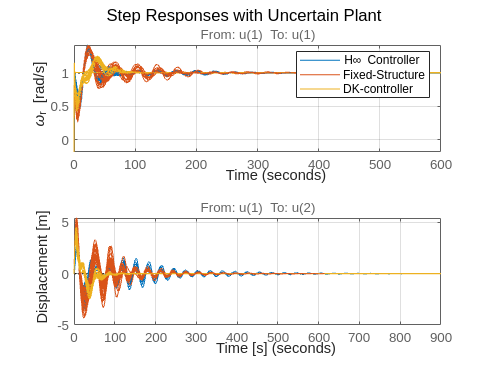


% Fixed-structure Controller
CL_fs = feedback(-Kfb_opt*X, eye(2));

% DK controller
CL_dk = feedback(DK*-X, eye(2));


figure

% input 1 to output 1
subplot(2, 1, 1)
hold on
step(CLstep_hinf(1, 1))
step(CL_fs(1, 1))
step(CL_dk(1, 1))
title(' ')
ylabel('\omega_r [rad/s]')
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on

% input 1 to input 2
subplot(2, 1, 2)
hold on
step(CLstep_hinf(2, 1))
step(CL_fs(2, 1))
step(CL_dk(2, 1))
title(' ')
xlabel('Time [s]')
ylabel('Displacement [m]')
grid on;

sgtitle('Step Responses with Uncertain Plant');

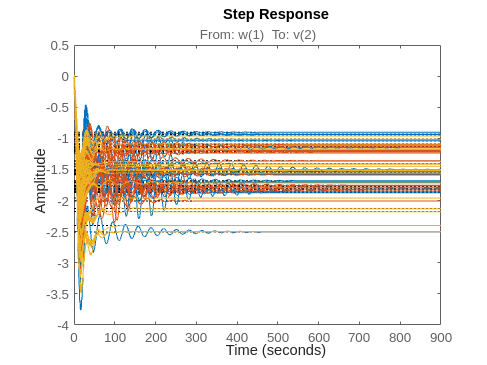

% Disturbance attenuation
CLhinf_d = connect(X, sumblock3, MS_C, {'w'}, {'v'});
CLfs_d = connect(X, sumblock3, Kfb_opt, {'w'}, {'v'});
CLdk_d = connect(X, sumblock3, DK, {'w'}, {'v'});

% Disturbance Response Hinf, FS, DK
figure
hold on
step(CLhinf_d(2,1))
step(CLfs_d(2,1))
step(CLdk_d(2,1))

### Frequency-domain

%bodemag
figure
bodemag(MS_C, Kfb_opt, DK)
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on

%sensitivity
hinf_sens = loopsens(G, MS_C);
fs_sens = loopsens(G, Kfb_opt);
dk_sens = loopsens(G, DK);

figure
bodemag(hinf_sens.Si, fs_sens.Si, dk_sens.Si)
title('Bode Diagram of Sensitivity Function')
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on

figure
bodemag(hinf_sens.Ti, fs_sens.Ti, dk_sens.Ti)
title('Bode Diagram of Complementary Sensitivity Function')
legend('H\infty Controller', 'Fixed-Structure', 'DK-controller')
grid on